% 第一题

clear,clc
[item, seq] = seq_limit;
fprintf('从第%d项开始,与前一项的差不超过0.001\n', item)

从第7项开始,与前一项的差不超过0.001


disp(seq)

    1.4142    1.8478    1.9616    1.9904    1.9976    1.9994    1.9998         0         0         0



% 第二题

clear,clc

degree = 50;
target = sind(degree);
x = (degree/360) * (2*pi);

vec = zeros(1,10); % 空间预分配
i = 1;

while abs(sum(vec)-target) > 10^(-7)
    vec(i) = ((-1)^(i-1)) * x^(2*i-1) / factorial(2*i-1);
    % 对下面表达式中的rand()作解释,因theta只知其存在性,不知其具体值
    % 故用rand()近似代替cos(theta*x)
    vec(i+1) = ((-1)^(i+1)) * rand() * x^(2*i+3) / factorial(2*i+3);
    i = i + 1;
end

m = i;

disp(target)

    0.7660



disp(sum(vec))

    0.7660



fprintf('m = \n')

m = 


disp(m)

     6



% 第三题

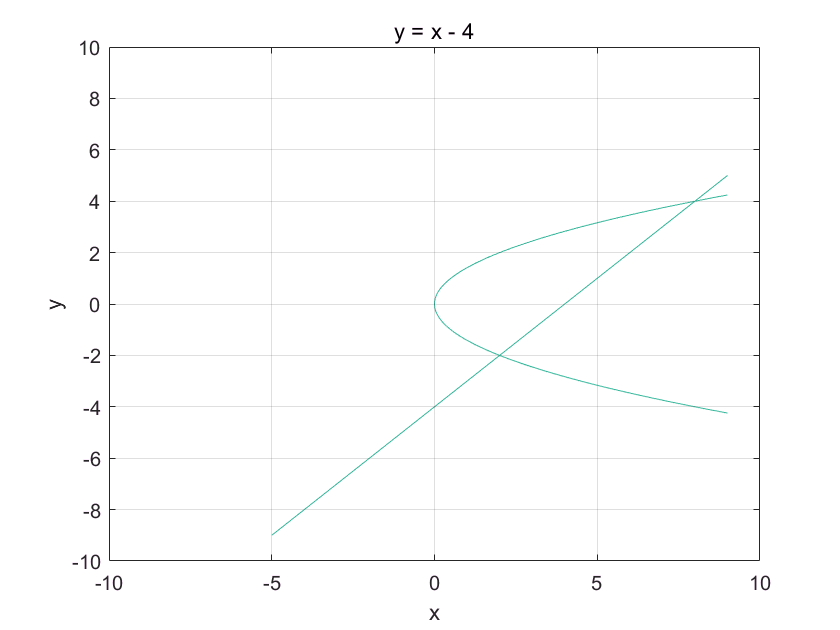

clear,clc

plotxy


syms x y
f1 =  y^2 / 2;
f2 =  y + 4;
y_point = solve(f1==f2);

t = int(f2-f1, y_point(1), y_point(2));

fprintf('t = \n')

t = 


disp(t)

$$18$$

% 第四题

clear,clc
fprintf('det(A) = \n')

det(A) = 


disp( ...
    det( ...
        diag(ones(1,10)*9) + ...
        diag(ones(1,9)*4, -1) + ...
        diag(ones(1,9)*5, 1) ...
    ) ...
)

    44633821



% 第五题

clear,clc

x =[11.2,11.5,14.5,17.1,19.6,20.4,24.2];
[p, nx1, nx0] = mx5(x);

fprintf('p = \n')

p = 


disp(p)

    0.1317
   10.2613



fprintf('nx1 = \n')

nx1 = 


disp(nx1)

   19.4323   26.6489   32.9749   38.5204   43.3816   47.6429   51.3784



fprintf('nx0 = \n')

nx0 = 


disp(nx0)

   11.2000    7.2165    6.3260    5.5455    4.8612    4.2613    3.7355



这是以上题目用到的"自定义函数"

function plotxy
% 此函数用于第三题

f1 = 'y^2 = 2*x';
f2 = 'y = x - 4';
figure(1)
ezplot(f1,[-9,9])
hold on 
ezplot(f2,[-9,9])
axis([-10, 10, -10, 10])
grid on

end

% ---------------------------

function [item_index, seq] = seq_limit
% 此函数用于第一题

seq_vec = zeros(1, 10); % 预分配向量
seq_vec(1) = sqrt(2); % 初始化a1
seq_vec(2) = sqrt(2 + seq_vec(1));

item_num = 2;
while (seq_vec(item_num) - seq_vec(item_num-1)) > 10^(-3)
    seq_vec(item_num+1) = sqrt(2 + seq_vec(item_num)); 
    item_num = item_num + 1;
end

item_index = item_num;
seq = seq_vec;
end

% ---------------------------

function [p, nx1, nx0] = mx5(x0)
% 此函数用于第五题
    
x1 = cumsum(x0);
z1 = 0.5*( x1(2:end) + x1(1:end-1) );
syms a b

% 模型
model_b = x0(2:end) + a.*z1(1:end);
% 模型的矩阵形式
B = [z1(1:end)', ones(length(z1),1)];
Y = x0(2:end)';
P = [a; b];
model_b_mat = [B*P Y];

p = inv(transpose(B) * B) * transpose(B) * Y;

a = p(1);
b = p(2);
nx1 = zeros(1, length(x0));
for i = 1: length(x0)
    nx1(i) = ( x0(1) - b/a )*exp(-a*i) + b/a;
end

nx0 = zeros(1, length(x0));
nx0(1) = x0(1);
nx0(2:end) = nx1(2:end) - nx1(1:end-1);

end